# Bridge of Doom

*Authors: *Dakota Chang, Kenneth Xiong

*Last Updated: *25 Feb, 2024

*Summary: *This computational essay presents Project 1 of the QEA2 Spring 2024 course, titled "Bridge of Doom." It delves into the mathematical modeling and practical application of steering a modified Neato robot along a predetermined parametric curve. The notebook is organized into several sections for ease of understanding: Section 1 covers the plotting of the path; Section 2 details the plotting of wheel velocities; Section 3 outlines the code implementation on the Neato robot; and Section 4 focuses on graphing sensor data to compare the robot's actual path against its planned trajectory.

## Section 1: Plotting the Path

% Define a scale factor for parameter t
beta = 0.2;

% Generate 1000 linearly spaced points between 0 and 3.2
points = linspace(0, 3.2, 1000);

% Calculate x and y coordinates for the parametric curve
x = 0.3960 * cos(2.65*(1.4 + points)); % x-coordinates based on a cosine function
y = -0.99 * sin(1.4 + points); % y-coordinates based on a sine function

% Declare symbolic variables for further calculations
syms u r t

% Define u as a scaled version of t
u = beta * t;

% Parametric equations for x, y, and z components
r_i = 0.3960 * cos(2.65*(1.4 + u)); % x-component of the curve
r_j = -0.99 * sin(1.4 + u); % y-component of the curve
r_k = 0 * u; % z-component of the curve (zero for 2D path)

% Assume t is a real number for symbolic computation
assume(t,'real');

% Combine the components to form the parametric curve vector
r = [r_i, r_j, r_k];

% Calculate the derivative of r with respect to t
drdu = diff(r,t);

% Calculate the unit tangent vector T_hat
T_hat = simplify(drdu./norm(drdu));

% Calculate the derivative of T_hat with respect to t
dT_hatdu = diff(T_hat,t);

% Calculate the unit normal vector N_hat
N_hat = dT_hatdu/norm(dT_hatdu);
N_hat = simplify(N_hat);

% Specific points to plot tangent and normal vectors
vecs = transpose(linspace(0.5, 3, 3));

% Calculate x and y coordinates at specific points
vecs_x = 0.3960 * cos(2.65*(1.4 + vecs));
vecs_y = -0.99 * sin(1.4 + vecs);

% Evaluate N_hat (normal vector) and T_hat (tangent vector) at specific points
N = eval(subs(N_hat, vecs/beta));
T = eval(subs(T_hat, vecs/beta));

Plot figure

beta = 0.2000

$$u = \frac{t}{5}$$

$$r\_i = \frac{99\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{250}$$

$$r\_j = -\frac{99\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)}{100}$$

$$r\_k = 0$$

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}^{2}} \end{array}$$

N =    -0.3061    0.9520         0
    0.7310    0.6824         0
    0.3456   -0.9384         0


T =     0.9520    0.3061         0
   -0.6824    0.7310         0
    0.9384    0.3456         0


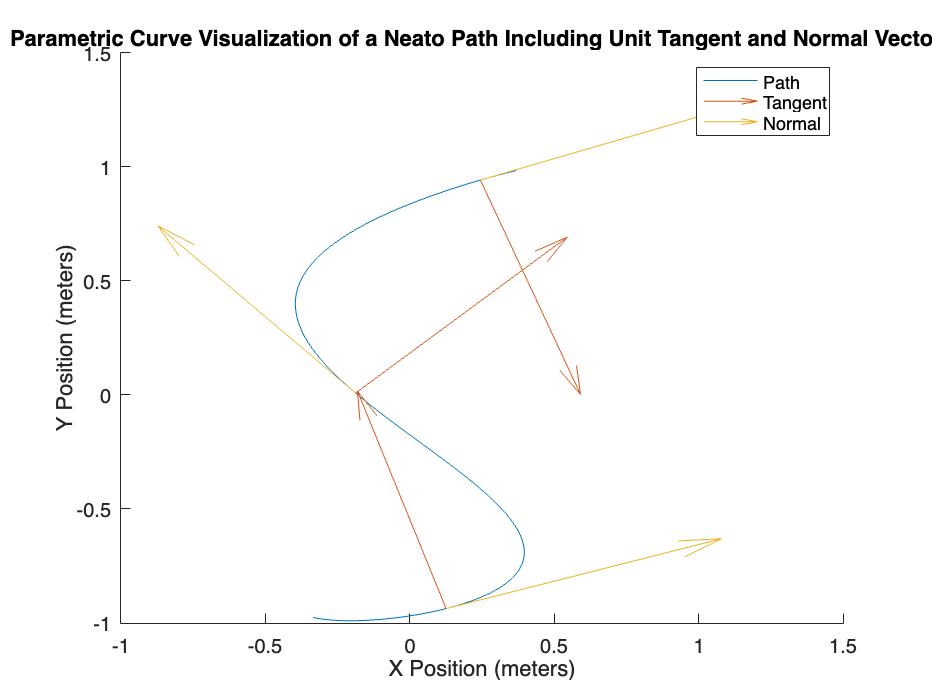

% Initialize figure for plotting
f = figure();
hold on;

% Plot the parametric curve
plot(x, y);
title('Parametric Curve Visualization of a Neato Path Including Unit Tangent and Normal Vectors');
xlabel('X Position (meters)');
ylabel('Y Position (meters)');

% Add quiver plots for tangent and normal vectors at specified points
quiver(vecs_x, vecs_y, N(:,1), N(:, 2)); % Normal vectors
quiver(vecs_x, vecs_y, T(:,1), T(:, 2)); % Tangent vectors

% Add legend to distinguish between path, tangent, and normal vectors
legend("Path", "Tangent", "Normal");

## Section 2: Plotting the Wheel Velocities

% Calculate velocity vector as derivative of position vector r w.r.t t.
vel = diff(r, t);

% Calculate angular velocity vector (omega) as cross product of T_hat and its derivative.
omega = cross(T_hat, diff(T_hat));

% Evaluate linear velocity (V_n) for points, normalizing to get speed at each point.
V_n = sqrt(sum((eval(subs(vel, transpose(points)/beta))).^2,2));

% Evaluate angular velocity at points, focusing on z-axis component for 2D motion.
ang_vel = eval(subs(omega, transpose(points)/beta));

% Plot linear and angular velocities.
figure; hold on;
plot(points, V_n); % Linear velocity
plot(points, ang_vel(:, 3)); % Angular velocity, z-axis component
legend("Linear Velocity", "Angular Velocity");

Calculating Left and Right Wheel Velocities

$$vel = \left(\begin{array}{ccc} -\frac{5247\,\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{25000} & -\frac{99\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)}{500} & 0 \end{array}\right)$$

$$ans = \begin{array}{l} \left(\begin{array}{ccc} -\frac{2809\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{100\,\sqrt{\sigma_{2}}}-\frac{53\,\sigma_{3}\,\sigma_{1}}{2\,{\sigma_{2}}^{3/2}} & \frac{10\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)}{\sqrt{\sigma_{2}}}-\frac{25\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)\,\sigma_{1}}{{\sigma_{2}}^{3/2}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1000\,\cos\left(\frac{t}{5}+\frac{7}{5}\right)\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)-\frac{148877\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)\,\sigma_{3}}{50}\\ \sigma_{2}=2500\,{\cos\left(\frac{t}{5}+\frac{7}{5}\right)}^{2}+2809\,{\sigma_{3}}^{2}\\ \sigma_{3}=\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right) \end{array}$$

$$omega = \begin{array}{l} \left(\begin{array}{ccc} 0 & 0 & -\frac{50\,\sigma_{4}\,\left(\frac{2809\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)}{100\,\sqrt{\sigma_{2}}}+\frac{53\,\sigma_{3}\,\sigma_{1}}{2\,{\sigma_{2}}^{3/2}}\right)}{\sqrt{\sigma_{2}}}-\frac{53\,\sigma_{3}\,\left(\frac{10\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)}{\sqrt{\sigma_{2}}}-\frac{25\,\sigma_{4}\,\sigma_{1}}{{\sigma_{2}}^{3/2}}\right)}{\sqrt{\sigma_{2}}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1000\,\sigma_{4}\,\sin\left(\frac{t}{5}+\frac{7}{5}\right)-\frac{148877\,\cos\left(\frac{53\,t}{100}+\frac{371}{100}\right)\,\sigma_{3}}{50}\\ \sigma_{2}=2500\,{\sigma_{4}}^{2}+2809\,{\sigma_{3}}^{2}\\ \sigma_{3}=\sin\left(\frac{53\,t}{100}+\frac{371}{100}\right)\\ \sigma_{4}=\cos\left(\frac{t}{5}+\frac{7}{5}\right) \end{array}$$

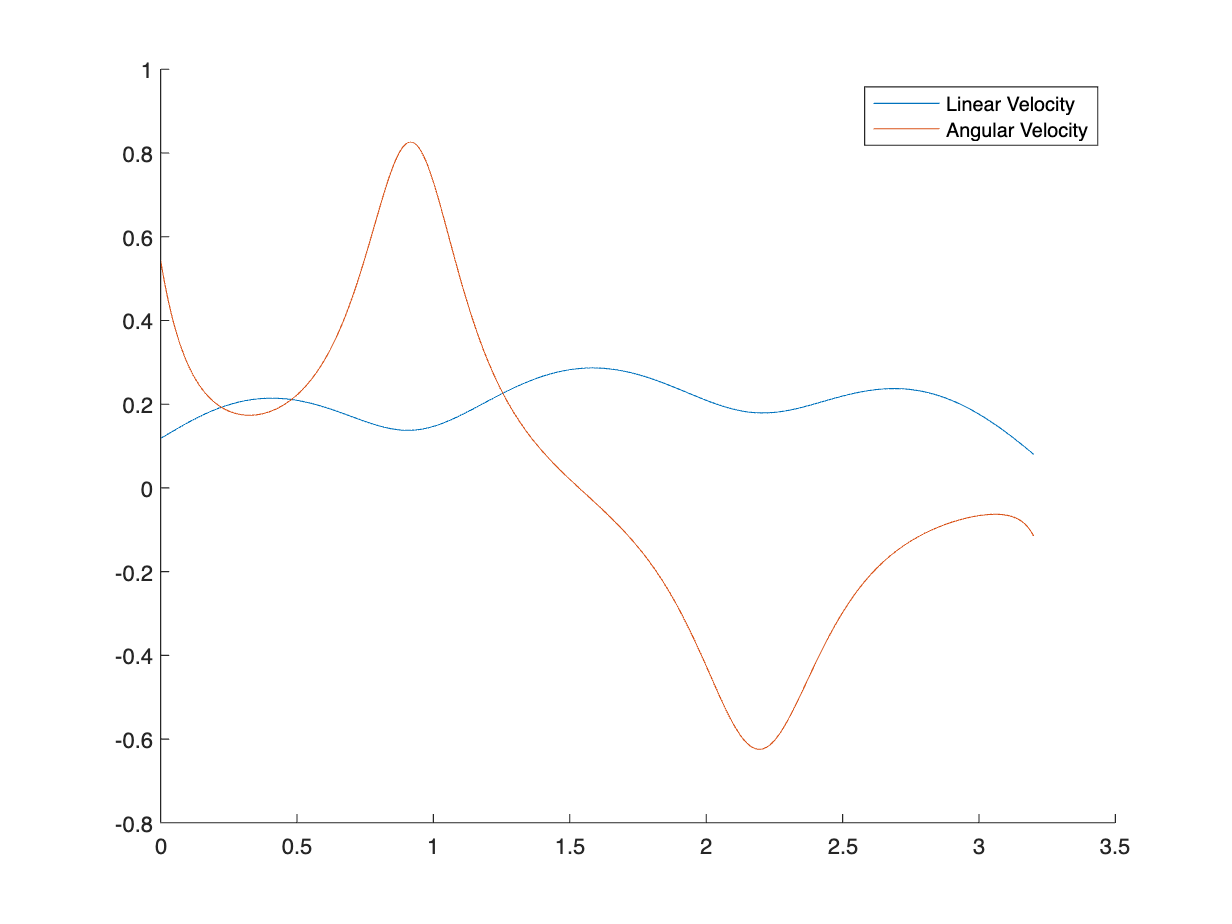

V_L =     0.0512
    0.0540
    0.0567
    0.0594
    0.0621
    0.0647
    0.0672
    0.0698
    0.0722
    0.0747


V_R =     0.1846
    0.1843
    0.1841
    0.1839
    0.1838
    0.1837
    0.1837
    0.1837
    0.1837
    0.1838


% Calculate velocities for left and right wheels based on linear and angular velocities.
V_L = V_n - ang_vel(:, 3) * 0.245/2; % Left wheel velocity
V_R = V_n + ang_vel(:, 3) * 0.245/2; % Right wheel velocity

## Section 3: Code Implementation on the Neato Robot

% Initial setup

% Assuming V_L and V_R are your vectors of length 1000
new_length = 1000 / 10; % Target length after averaging

% Data collection storage space initialization
max_points = new_length;

fig = gcf;

Setup complete. Press enter to start.


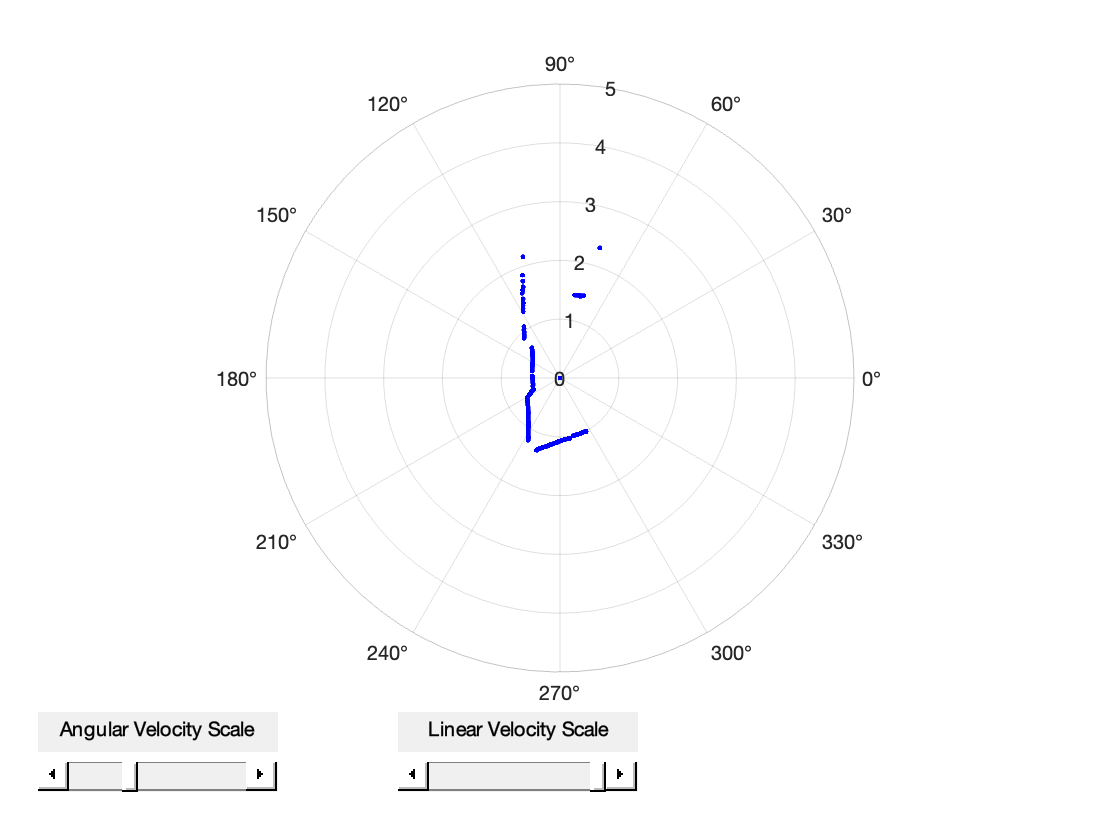

drivetime = 0.2; % s for each velocity pair
encoder_data = zeros(max_points,3);
iter = 0;

% Shorten V_L and V_R by averaging every 10 elements
V_L_short = mean(reshape(V_L, [10, length(V_L)/10]));
V_R_short = mean(reshape(V_R, [10, length(V_R)/10]));

% Now, incorporate V_L_short and V_R_short into the modified robot code
% [sensors,vels] = neatoSim(); % Uncomment for simulator
[sensors,vels] = neato('192.168.16.67'); % Uncomment for physical neato

fig = gcf;

for idx = 1:length(V_L_short) % Using shortened vectors
    vl = V_L_short(idx);
    vr = V_R_short(idx);
    disp(['Running with vl = ', num2str(vl), ' and vr = ', num2str(vr)]);
    tic;
    t = toc;
    while t < drivetime
        t = toc; % Update t
        vels.lrWheelVelocitiesInMetersPerSecond = [vl, vr]; 
    end
    sensors.encoders
    if isempty(sensors.encoders) == 0
        iter=iter+1;
        if iter<=max_points
            encoder_data(iter,:)=[t,sensors.encoders(1),sensors.encoders(2)];
        end
    end



    % Stop the robot after the drive time for the current velocity pair
    vels.lrWheelVelocitiesInMetersPerSecond = [0, 0];
    %pause(0.1); % Pause to stabilize before the next iteration
end

Running with vl = 0.063206 and vr = 0.18391



ans =

     []



Running with vl = 0.08721 and vr = 0.1849



ans =

     []



Running with vl = 0.10764 and vr = 0.18868



ans =

     []



Running with vl = 0.12518 and vr = 0.1941



ans =

     []



Running with vl = 0.14026 and vr = 0.20034


ans =     0.0580    0.0820


Running with vl = 0.15318 and vr = 0.20682


ans =     0.1630    0.2290


Running with vl = 0.16411 and vr = 0.21314


ans =     0.2230    0.3110


Running with vl = 0.17316 and vr = 0.21901


ans =     0.2550    0.3520


Running with vl = 0.18041 and vr = 0.22423


ans =     0.2880    0.3960


Running with vl = 0.18589 and vr = 0.22866


ans =     0.3220    0.4380


Running with vl = 0.18963 and vr = 0.23222


ans =     0.3590    0.4850


Running with vl = 0.19164 and vr = 0.23485


ans =     0.3980    0.5330


Running with vl = 0.19194 and vr = 0.23654


ans =     0.4340    0.5760


Running with vl = 0.19054 and vr = 0.23734


ans =     0.4710    0.6220


Running with vl = 0.18746 and vr = 0.23728


ans =     0.5100    0.6690


Running with vl = 0.18271 and vr = 0.23648


ans =     0.5460    0.7140


Running with vl = 0.17631 and vr = 0.23506


ans =     0.5850    0.7630


Running with vl = 0.1683 and vr = 0.23319


ans =     0.6210    0.8100


Running with vl = 0.15871 and vr = 0.23108


ans =     0.6540    0.8560


Running with vl = 0.14759 and vr = 0.22899


ans =     0.6870    0.9040


Running with vl = 0.13502 and vr = 0.22718


ans =     0.7510    0.9970


Running with vl = 0.12116 and vr = 0.22597


ans =     0.7770    1.0390


Running with vl = 0.10625 and vr = 0.22563


ans =     0.8040    1.0850


Running with vl = 0.090682 and vr = 0.22637


ans =     0.8280    1.1330


Running with vl = 0.075123 and vr = 0.22824


ans =     0.8490    1.1750


Running with vl = 0.060558 and vr = 0.23103


ans =     0.8670    1.2210


Running with vl = 0.048314 and vr = 0.23422


ans =     0.8810    1.2630


Running with vl = 0.03991 and vr = 0.23703


ans =     0.8930    1.3090


Running with vl = 0.036696 and vr = 0.23872


ans =     0.9030    1.3560


Running with vl = 0.039392 and vr = 0.23889


ans =     0.9100    1.4020


Running with vl = 0.047806 and vr = 0.23774


ans =     0.9180    1.4480


Running with vl = 0.060933 and vr = 0.23596


ans =     0.9270    1.4960


Running with vl = 0.077356 and vr = 0.23442


ans =     0.9350    1.5410


Running with vl = 0.095678 and vr = 0.23383


ans =     0.9480    1.5910


Running with vl = 0.11478 and vr = 0.23459


ans =     0.9650    1.6380


Running with vl = 0.13388 and vr = 0.23677


ans =     0.9820    1.6810


Running with vl = 0.15248 and vr = 0.24023


ans =     1.0080    1.7310


Running with vl = 0.17026 and vr = 0.24471


ans =     1.0340    1.7750


Running with vl = 0.18705 and vr = 0.2499


ans =     1.0640    1.8200


Running with vl = 0.20274 and vr = 0.25547


ans =     1.0980    1.8670


Running with vl = 0.21725 and vr = 0.26114


ans =     1.1330    1.9120


Running with vl = 0.23054 and vr = 0.26663


ans =     1.1740    1.9610


Running with vl = 0.24256 and vr = 0.27172


ans =     1.2170    2.0110


Running with vl = 0.2533 and vr = 0.2762


ans =     1.2640    2.0610


Running with vl = 0.26273 and vr = 0.27992


ans =     1.3110    2.1100


Running with vl = 0.27084 and vr = 0.28272


ans =     1.3560    2.1610


Running with vl = 0.27763 and vr = 0.2845


ans =     1.4130    2.2230


Running with vl = 0.28312 and vr = 0.28517


ans =     1.4610    2.2710


Running with vl = 0.28732 and vr = 0.28466


ans =     1.5130    2.3210


Running with vl = 0.29027 and vr = 0.28291


ans =     1.6590    2.4630


Running with vl = 0.29202 and vr = 0.27989


ans =     1.7630    2.5620


Running with vl = 0.29264 and vr = 0.2756


ans =     1.8710    2.6660


Running with vl = 0.29221 and vr = 0.27002


ans =     1.9710    2.7650


Running with vl = 0.29083 and vr = 0.26318


ans =     2.0240    2.8180


Running with vl = 0.28863 and vr = 0.2551


ans = 1×2
    2.1350    2.9290


Running with vl = 0.28575 and vr = 0.24584


ans = 1×2
    2.1910    2.9850


Running with vl = 0.28233 and vr = 0.23546


ans = 1×2
    2.2480    3.0410


Running with vl = 0.27857 and vr = 0.22404


ans = 1×2
    2.3600    3.1420


Running with vl = 0.27466 and vr = 0.21172


ans = 1×2
    2.4120    3.1850


Running with vl = 0.2708 and vr = 0.19862


ans = 1×2
    2.4660    3.2310


Running with vl = 0.26719 and vr = 0.18495


ans = 1×2
    2.5200    3.2730


Running with vl = 0.264 and vr = 0.17097


ans = 1×2
    2.6220    3.3500


Running with vl = 0.26139 and vr = 0.15701


ans = 1×2
    2.6710    3.3840


Running with vl = 0.25942 and vr = 0.1435


ans = 1×2
    2.7200    3.4160


Running with vl = 0.25809 and vr = 0.13098


ans = 1×2
    2.7700    3.4470


Running with vl = 0.25727 and vr = 0.12006


ans = 1×2
    2.8190    3.4760


Running with vl = 0.25676 and vr = 0.1114


ans = 1×2
    2.8690    3.5020


Running with vl = 0.25634 and vr = 0.10557


ans = 1×2
    2.9180    3.5260


Running with vl = 0.2558 and vr = 0.10298


ans = 1×2
    2.9680    3.5480


Running with vl = 0.25506 and vr = 0.10377


ans = 1×2
    3.0170    3.5700


Running with vl = 0.25416 and vr = 0.10774


ans = 1×2
    3.0660    3.5900


Running with vl = 0.25325 and vr = 0.11443


ans = 1×2
    3.1130    3.6110


Running with vl = 0.25255 and vr = 0.12323


ans = 1×2
    3.1630    3.6320


Running with vl = 0.25221 and vr = 0.13343


ans = 1×2
    3.2150    3.6560


Running with vl = 0.25234 and vr = 0.14441


ans = 1×2
    3.3150    3.7070


Running with vl = 0.25292 and vr = 0.15562


ans = 1×2
    3.3640    3.7350


Running with vl = 0.25388 and vr = 0.1666


ans = 1×2
    3.4150    3.7640


Running with vl = 0.25508 and vr = 0.17703


ans = 1×2
    3.4640    3.7950


Running with vl = 0.25633 and vr = 0.18664


ans = 1×2
    3.5150    3.8280


Running with vl = 0.25746 and vr = 0.19524


ans = 1×2
    3.5630    3.8630


Running with vl = 0.25826 and vr = 0.20268


ans = 1×2
    3.6080    3.8990


Running with vl = 0.25856 and vr = 0.20886


ans = 1×2
    3.6430    3.9380


Running with vl = 0.25822 and vr = 0.21368


ans = 1×2
    3.6820    3.9790


Running with vl = 0.25707 and vr = 0.2171


ans = 1×2
    3.7180    4.0180


Running with vl = 0.25502 and vr = 0.21907


ans = 1×2
    3.7580    4.0590


Running with vl = 0.25197 and vr = 0.21955


ans = 1×2
    3.7990    4.1020


Running with vl = 0.24784 and vr = 0.21853


ans = 1×2
    3.8800    4.1850


Running with vl = 0.24259 and vr = 0.21601


ans = 1×2
    3.9210    4.2280


Running with vl = 0.23617 and vr = 0.212


ans = 1×2
    3.9620    4.2710


Running with vl = 0.22857 and vr = 0.20651


ans = 1×2
    4.0000    4.3120


Running with vl = 0.2198 and vr = 0.19956


ans = 1×2
    4.0420    4.3560


Running with vl = 0.20988 and vr = 0.19119


ans = 1×2
    4.0840    4.3980


Running with vl = 0.19885 and vr = 0.18145


ans = 1×2
    4.1250    4.4410


Running with vl = 0.18677 and vr = 0.17037


ans = 1×2
    4.1670    4.4800


Running with vl = 0.17372 and vr = 0.15799


ans = 1×2
    4.2070    4.5160


Running with vl = 0.15981 and vr = 0.14435


ans = 1×2
    4.2450    4.5480


Running with vl = 0.1452 and vr = 0.12946


ans = 1×2
    4.2860    4.5800


Running with vl = 0.13012 and vr = 0.11326


ans = 1×2
    4.3250    4.6090


Running with vl = 0.11495 and vr = 0.095567


ans = 1×2
    4.3560    4.6340


Running with vl = 0.10041 and vr = 0.075882


ans = 1×2
    4.3820    4.6560



% Clean up
close(fig); % Close the figure at the end of all iterations
disp('Data collection complete.');

Data collection complete.


## Section 4: Graphing Sensor Data to Compare the Robot’s Actual Path against Its Planned Trajectory.

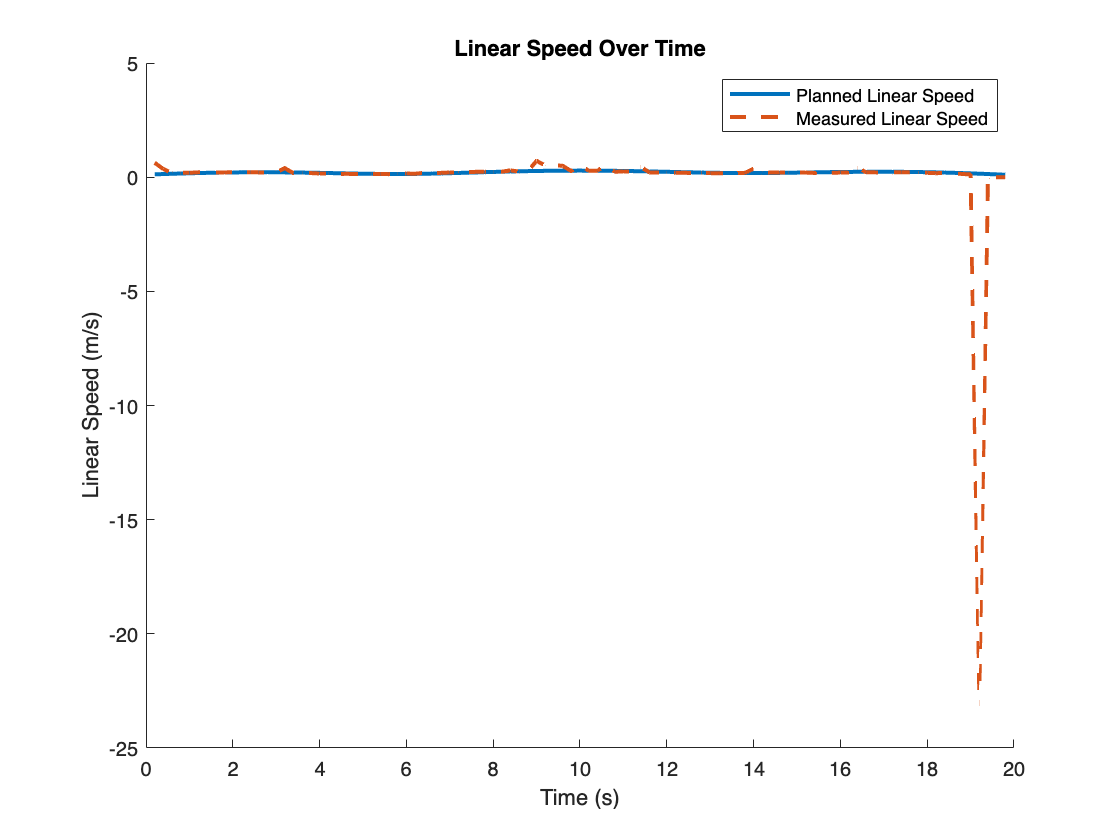

% Parameters
wheel_base = 0.245; % Distance between the wheels in meters

% Initialization
x_pos = 0; % Initial x position
y_pos = 0; % Initial y position
theta = 0; % Initial orientation angle in radians

% Calculate measured linear speed and angular velocity
measured_linear_speeds = zeros(max_points-1, 1);
measured_angular_velocities = zeros(max_points-1, 1);

for i = 2:max_points
    delta_left = (encoder_data(i,2) - encoder_data(i-1,2));
    delta_right = (encoder_data(i,3) - encoder_data(i-1,3));
    delta_time = drivetime; % Assuming constant drive time between measurements
    
    % Linear speed is the average of the left and right wheel speeds
    measured_linear_speeds(i-1) = (delta_left + delta_right) / (2 * delta_time);
    
    % Angular velocity is the difference in wheel speeds divided by the wheelbase, considering the direction
    measured_angular_velocities(i-1) = (delta_right - delta_left) / (wheel_base * delta_time);
end

% Time array for plotting
time_array = (1:max_points-1) * drivetime;

% Plot Linear Speed
% subplot(2, 1, 1); % Two rows, one column, first subplot
figure;
hold on;
V_n_short = mean(reshape(V_n, [10, length(V_n)/10]));
plot(time_array, V_n_short(1:99), 'LineWidth', 2); % Planned linear speed in solid line
plot(time_array, measured_linear_speeds, '--', 'LineWidth', 2); % Measured linear speed in dashed line
title('Linear Speed Over Time');
xlabel('Time (s)');
ylabel('Linear Speed (m/s)');
legend('Planned Linear Speed', 'Measured Linear Speed');
hold off;

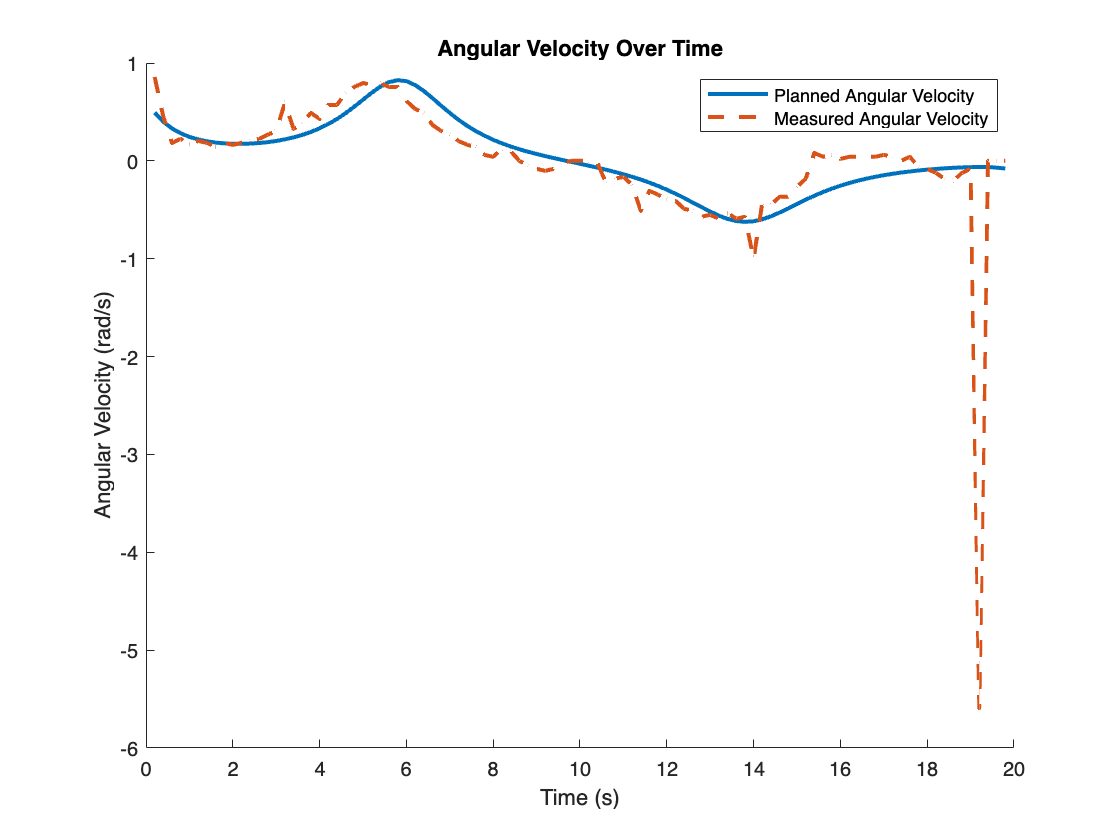


% Plot Angular Velocity
% subplot(2, 1, 2); % Two rows, one column, second subplot
figure;
hold on;
planned_angular_velocities = mean(reshape(ang_vel(:, 3), [10, length(ang_vel(:, 3))/10]));
plot(time_array, planned_angular_velocities(1:99), 'LineWidth', 2); % Planned angular velocity in solid line
plot(time_array, measured_angular_velocities, '--', 'LineWidth', 2); % Measured angular velocity in dashed line
title('Angular Velocity Over Time');
xlabel('Time (s)');
ylabel('Angular Velocity (rad/s)');
legend('Planned Angular Velocity', 'Measured Angular Velocity');
hold off;

% Assuming wheel_radius and encoder_resolution are defined as before
% Calculate measured left and right wheel velocities from encoder data
measured_V_L = zeros(max_points-1, 1);
measured_V_R = zeros(max_points-1, 1);

for i = 2:max_points
    delta_left = (encoder_data(i,2) - encoder_data(i-1,2));
    delta_right = (encoder_data(i,3) - encoder_data(i-1,3));
    delta_time = drivetime; % Time interval between measurements
    
    % Wheel velocities in meters per second
    measured_V_L(i-1) = delta_left / delta_time;
    measured_V_R(i-1) = delta_right / delta_time;
end


% Plotting
figure; % Start a new figure
figure('Position',[600 100 1500 1000]);
hold on; % Hold on for multiple plots
disp(time_array)

    0.2000    0.4000    0.6000    0.8000    1.0000    1.2000    1.4000    1.6000    1.8000    2.0000    2.2000    2.4000    2.6000    2.8000    3.0000    3.2000    3.4000    3.6000    3.8000    4.0000    4.2000    4.4000    4.6000    4.8000    5.0000    5.2000    5.4000    5.6000    5.8000    6.0000    6.2000    6.4000    6.6000    6.8000    7.0000    7.2000    7.4000    7.6000    7.8000    8.0000    8.2000    8.4000    8.6000    8.8000    9.0000    9.2000    9.4000    9.6000    9.8000   10.0000   10.2000   10.4000   10.6000   10.8000   11.0000   11.2000   11.4000   11.6000   11.8000   12.0000   12.2000   12.4000   12.6000   12.8000   13.0000   13.2000   13.4000   13.6000   13.8000   14.0000   14.2000   14.4000   14.6000   14.8000   15.0000   15.2000   15.4000   15.6000   15.8000   16.0000   16.2000   16.4000   16.6000   16.8000   17.0000   17.2000   17.4000   17.6000   17.8000   18.0000   18.2000   18.4000   18.6000   18.8000   19.0000   19.2000   19.4000   19.6000   19.8000



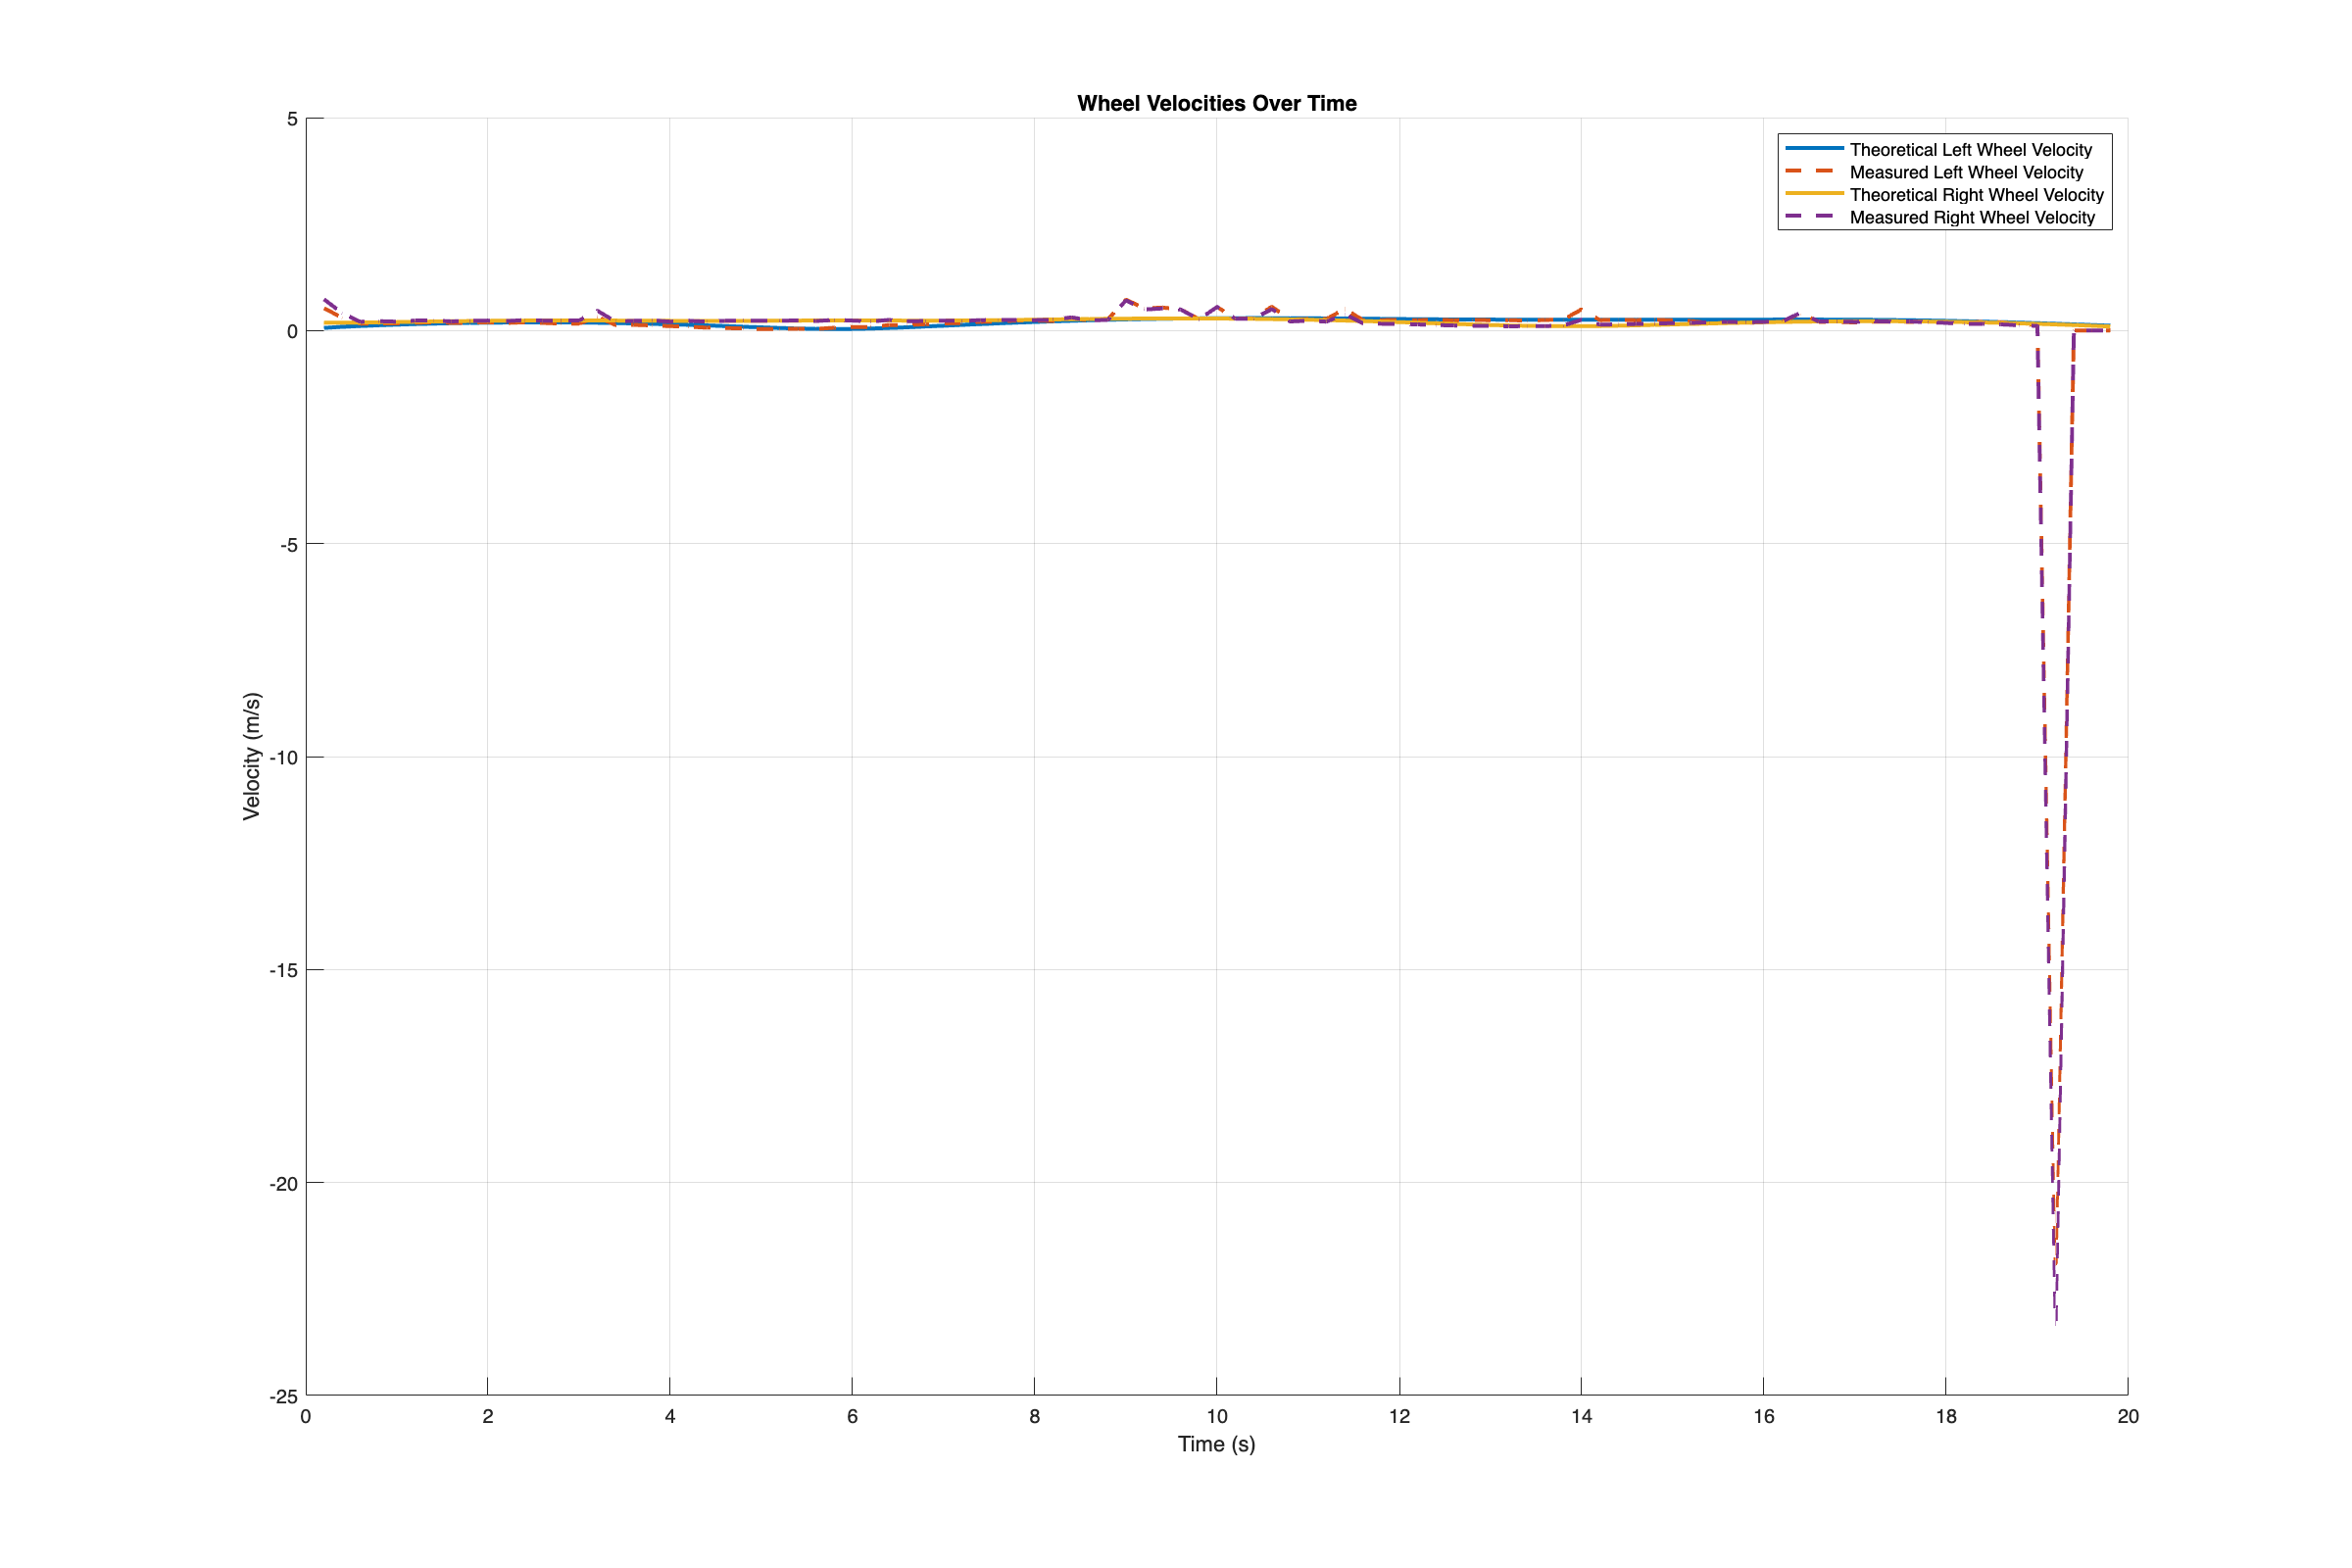

% Theoretical Left Wheel Velocity
plot(time_array, V_L_short(1:99), 'LineWidth', 2, 'DisplayName', 'Theoretical Left Wheel Velocity');

% Measured Left Wheel Velocity
plot(time_array, measured_V_L, '--', 'LineWidth', 2, 'DisplayName', 'Measured Left Wheel Velocity');

% Theoretical Right Wheel Velocity
plot(time_array, V_R_short(1:99), 'LineWidth', 2, 'DisplayName', 'Theoretical Right Wheel Velocity');

% Measured Right Wheel Velocity
plot(time_array, measured_V_R, '--', 'LineWidth', 2, 'DisplayName', 'Measured Right Wheel Velocity');

% Configure the plot
title('Wheel Velocities Over Time');
xlabel('Time (s)');
ylabel('Velocity (m/s)');
legend('show');
grid on;
hold off;

% Storage for position and orientation
x_trajectory = zeros(max_points, 1);
y_trajectory = zeros(max_points, 1);
theta_trajectory = zeros(max_points, 1);

% Calculate the trajectory
for i = 2:max_points
    % Calculate the distance each wheel traveled in meters
    delta_left = (encoder_data(i,2) - encoder_data(i-1,2));
    delta_right = (encoder_data(i,3) - encoder_data(i-1,3));
    
    % Avg distance traveled
    delta_center = (delta_left + delta_right) / 2;
    
    % Change in orientation
    delta_theta = (delta_right - delta_left) / wheel_base;
    
    % Update orientation
    theta = theta + delta_theta;
    
    % Update position
    x_pos = x_pos + delta_center * cos(theta);
    y_pos = y_pos + delta_center * sin(theta);
    
    % Store trajectory
    x_trajectory(i) = x_pos;
    y_trajectory(i) = y_pos;
    theta_trajectory(i) = theta;
end

% Number of points in the trajectory
numPointsSensorPath = length(x_trajectory);

% Preallocate arrays for derivatives and vectors for the entire sensor path
deltaXSensorPath = zeros(numPointsSensorPath, 1);
deltaYSensorPath = zeros(numPointsSensorPath, 1);
tangentVectorXAllPoints = zeros(numPointsSensorPath, 1);
tangentVectorYAllPoints = zeros(numPointsSensorPath, 1);
normalVectorXAllPoints = zeros(numPointsSensorPath, 1);
normalVectorYAllPoints = zeros(numPointsSensorPath, 1);

% Calculate discrete derivatives (differences) for x and y for the entire sensor path
for index = 2:numPointsSensorPath-1
    deltaXSensorPath(index) = (x_trajectory(index+1) - x_trajectory(index-1))/2;
    deltaYSensorPath(index) = (y_trajectory(index+1) - y_trajectory(index-1))/2;
end

% Calculate unit tangent vectors for the entire sensor path
for index = 1:numPointsSensorPath
    magnitude = sqrt(deltaXSensorPath(index)^2 + deltaYSensorPath(index)^2);
    if magnitude ~= 0
        tangentVectorXAllPoints(index) = deltaXSensorPath(index) / magnitude;
        tangentVectorYAllPoints(index) = deltaYSensorPath(index) / magnitude;
    end
end

% Calculate derivatives of the tangent vectors to get the change in tangent vectors across the path
deltaTangentVectorX = diff(tangentVectorXAllPoints);
deltaTangentVectorY = diff(tangentVectorYAllPoints);
deltaTangentVectorX = [deltaTangentVectorX; 0]; % Adjust size to match original array
deltaTangentVectorY = [deltaTangentVectorY; 0]; % Adjust size to match original array

% Calculate unit normal vectors for the entire sensor path
for index = 1:numPointsSensorPath
    magnitudeNormal = sqrt(deltaTangentVectorX(index)^2 + deltaTangentVectorY(index)^2);
    if magnitudeNormal ~= 0
        normalVectorXAllPoints(index) = deltaTangentVectorX(index) / magnitudeNormal;
        normalVectorYAllPoints(index) = deltaTangentVectorY(index) / magnitudeNormal;
    end
end

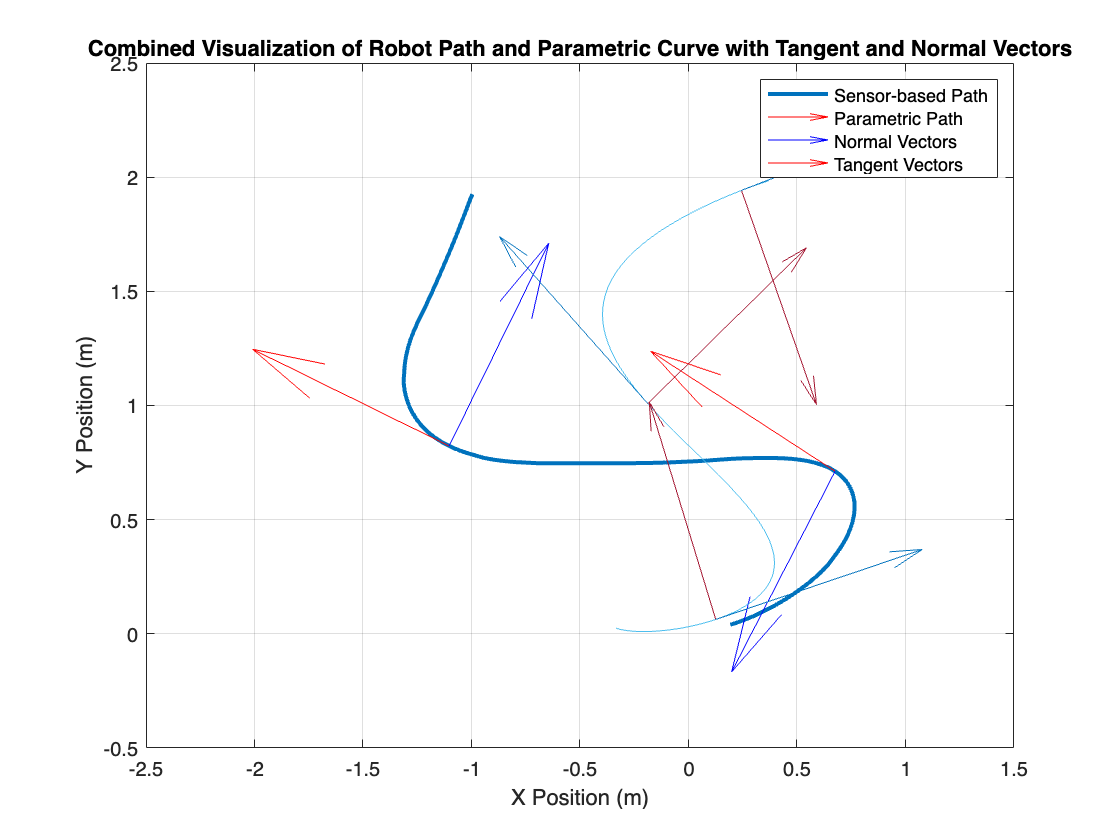

% Plotting the sensor path
figure;
plot(x_trajectory(3:90), y_trajectory(3:90), 'LineWidth', 2);
hold on;

% Select a specific point to plot tangent and normal vectors
specificIndexForVectors = 30;

% Define the vectors for the chosen point
specificTangentVectorX = tangentVectorXAllPoints(specificIndexForVectors);
specificTangentVectorY = tangentVectorYAllPoints(specificIndexForVectors);
specificNormalVectorX = normalVectorXAllPoints(specificIndexForVectors);
specificNormalVectorY = normalVectorYAllPoints(specificIndexForVectors);

% Add quivers for unit tangent and normal vectors at the specified point
quiver(x_trajectory(specificIndexForVectors), y_trajectory(specificIndexForVectors), specificTangentVectorX, specificTangentVectorY, 'r', 'AutoScale', 'off', 'MaxHeadSize', 2, 'DisplayName', 'Tangent Vector at Specific Point');
quiver(x_trajectory(specificIndexForVectors), y_trajectory(specificIndexForVectors), specificNormalVectorX, specificNormalVectorY, 'b', 'AutoScale', 'off', 'MaxHeadSize', 2, 'DisplayName', 'Normal Vector at Specific Point');

% Select a specific point to plot tangent and normal vectors
specificIndexForVectors = 60;

% Define the vectors for the chosen point
specificTangentVectorX = tangentVectorXAllPoints(specificIndexForVectors);
specificTangentVectorY = tangentVectorYAllPoints(specificIndexForVectors);
specificNormalVectorX = normalVectorXAllPoints(specificIndexForVectors);
specificNormalVectorY = normalVectorYAllPoints(specificIndexForVectors);

% Add quivers for unit tangent and normal vectors at the specified point
quiver(x_trajectory(specificIndexForVectors), y_trajectory(specificIndexForVectors), specificTangentVectorX, specificTangentVectorY, 'r', 'AutoScale', 'off', 'MaxHeadSize', 2, 'DisplayName', 'Tangent Vector at Specific Point');
quiver(x_trajectory(specificIndexForVectors), y_trajectory(specificIndexForVectors), specificNormalVectorX, specificNormalVectorY, 'b', 'AutoScale', 'off', 'MaxHeadSize', 2, 'DisplayName', 'Normal Vector at Specific Point');

% Plot original parametric curve
plot(x, y+1);


% Add quivers for unit tangent and normal vectors at specified points
quiver(vecs_x, vecs_y+1, N(:,1), N(:, 2), 'AutoScale', 'off');
quiver(vecs_x, vecs_y+1, T(:,1), T(:, 2), 'AutoScale', 'off');

% Configure the plot
xlabel('X Position (m)');
ylabel('Y Position (m)');
title('Combined Visualization of Robot Path and Parametric Curve with Tangent and Normal Vectors');
legend('Sensor-based Path', 'Parametric Path', 'Normal Vectors', 'Tangent Vectors');
% axis equal;
grid on;

% Release the hold
hold off;